%%  Разбор данных
% запись путей
addpath(genpath('E:\ExchangeRateStability\MotorcycleBooks\Models'))


% загрузить данные
path_data = 'E:\ExchangeRateStability\Log'

path_data = 'E:\ExchangeRateStability\Log'

%name_file = "20210930_1_50kg_200kmh"

name_file = "T3_2021-10-08_10-33"

name_file = "T3_2021-10-08_10-33"


load('-mat', path_data+"\"+name_file+'.mat');


% разность между колесами
disp("погрешность смещения")

погрешность смещения


z=DanConvert.vBelt.F - DanConvert.vBelt.R;
Vxerror=zeros(length(DanConvert.vBelt.F),1);
for i = 1:length(DanConvert.vBelt.F)
    Vxerror(i)= z(i)/max(DanConvert.vBelt.F(i), DanConvert.vBelt.R(i));
end
Vxerror(1:10)=0;

% тест формулы 1-(V/w*R)
r0 = 25.4*17/1000;
%V = DanConvert.speed;
V = DanConvert.vBelt.F;
kp=3;
%w0=2*pi*f
vr=r0*DanConvert.Engine.Rotv/kp;
s0 = 1-(V./(vr))

s0 =    -0.7633   -0.7940   -0.6484   -0.6419   -0.6317   -0.6303   -0.6306   -0.6309   -0.6313   -0.6316   -0.6320   -0.6324   -0.6328   -0.6332   -0.6331   -0.6313   -0.6268   -0.5153   -0.2609   -0.0224    0.1449    0.2671    0.2863    0.2991    0.3118    0.3240    0.3361    0.3481    0.3604    0.3733    0.3864    0.4000    0.4139    0.4282    0.4428    0.4577    0.4727    0.4877    0.5028    0.5177    0.5324    0.5468    0.5606    0.5738    0.5864    0.5977    0.6049    0.6078    0.6089    0.6091


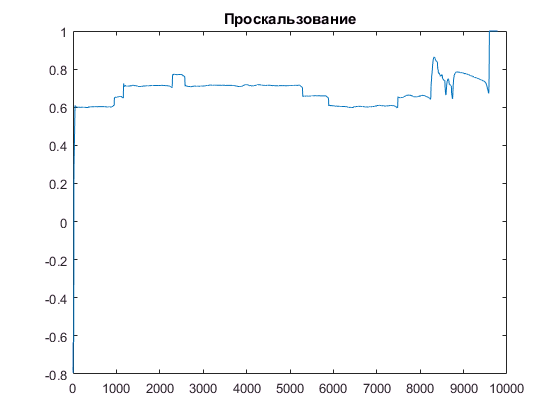

figure
plot(s0)
title("Проскальзование")

%  расчет mu

fx = DanConvert.Frc.X;
nx = DanConvert.Frc.Z;
muu = fx./nx

muu =    -0.0012   -0.0210   -0.0188   -0.0195   -0.0194   -0.0195   -0.0195   -0.0196   -0.0196   -0.0197   -0.0197   -0.0198   -0.0174   -0.0170   -0.0169   -0.0168   -0.0167   -0.8130   -1.0848   -1.0826   -1.0835   -1.0844   -1.0853   -1.0857   -1.0858   -1.0857   -1.0856   -1.0854   -1.0852   -1.0849   -1.0847   -1.0845   -1.0842   -1.0840   -1.0837   -1.0834   -1.0831   -1.0829   -1.0827   -1.0825   -1.0823   -1.0822   -1.0822   -1.0822   -1.0521   -0.6099    0.3367    0.7367    0.8629    0.9096


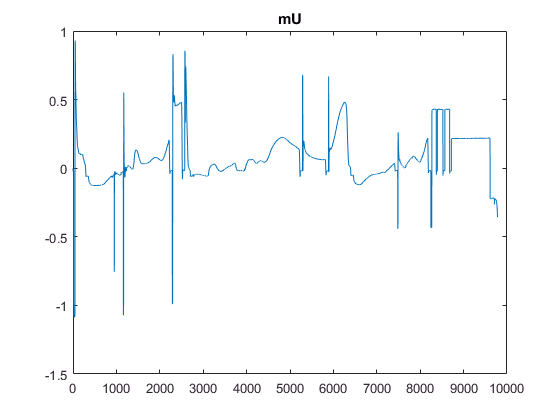

figure
plot(muu)
title("mU")

Undefined function or variable 'w0'.

% филтер Калман

[x(:,3), x(:,2),  x(:,1)] = MasKalman(DanConvert.XYZg.RollVel');
[y(:,3), y(:,2),  y(:,1)] = MasKalman(DanConvert.XYZg.PitchVel');
[z(:,3), z(:,2),  z(:,1)] = MasKalman(DanConvert.XYZg.YawVel');
dt=0.01

dt = 0.0100

for i = 1:length(x(:,1))
    state = [x(i,1); x(i,2); x(i,3); y(i,1); y(i,2); y(i,3); z(i,1); z(i,2); z(i,3)];
    m(i,:)= constacc(state, dt);
end


Error using coder.internal.errorIf (line 8)
The size of the state vector does not fit the motion model.

Error in constacc (line 76)
coder.internal.errorIf(cond, 'driving:motion:incorrectStateSize');

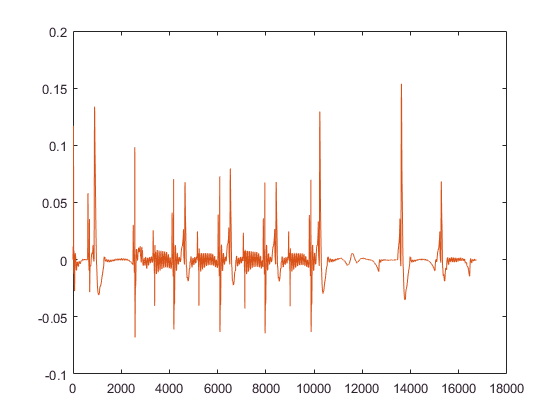

mx(:,1)=y(:,1);
mx(:,2)=m(:,4);
plot(mx,'DisplayName','mx')

% подключение FFT
step = 10;
nfft = 128*2;
limit = 20;
count = length(DanConvert.Time);
Npoint = fix(count/step);
t=linspace(1,limit, limit);
myFFT = MyFFT(DanConvert.Time, DanConvert.XYZg.YawAcc, step, nfft, limit); 
%myFFT = MyFFT(Dan1.Time, Vxerror, step, nfft, limit); 
k=1;
i=1

i = 1

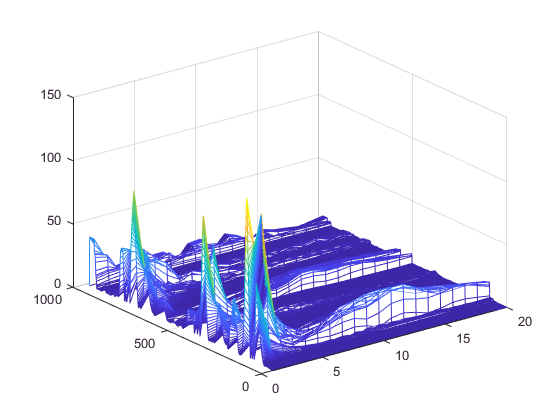

M=zeros(Npoint,limit);
V=zeros(Npoint,2);
Verror=zeros(Npoint,1);
while i<Npoint
%for i = 1:Npoint
    %timex=string(k*0.01)+" Sec."
    Y = myFFT.OneStep(k);
    M(i,:)=Y;
%    k0=k; if k0>count k0=count end
    %V(i, 1)=Dan1.vBelt.F(k0);
    %V(i, 2)=Dan1.vBelt.R(k0);
    %Verror(i)=(Dan1.vBelt.F(k0) -Dan1.vBelt.R(k0))/max(Dan1.vBelt.F(k0), Dan1.vBelt.R(k0));
%    figure;%    plot(t,Y)%    grid on;
    k=k+step;
    i=i+1;
end    
figure;
mesh(M)

function [z, vx, w] = MasKalman(w)
    function p=f0(w0)
        count = length(w0);
        vxx=[0.0; w0];
        vxx=vxx(1: count);
        p=vxx-w0;
    end
    vx=f0(w);
    z=f0(vx);
end

